# Sincronización de un sistema caótico de múltiple enrollamiento mediante un observador de estado extendido

Autor(a): RAMON RAMIREZ VILLALOBOS, TECNOLÓGICO NACIONAL DE MÉXICO / Instituto Tecnológico de Tijuana

## Resumen

*Este estudio presenta el diseño de un observador para resolver el problema de sincronización de un sistema caóticos de múltiple enrollamiento. La propuesta consiste en el diseño de un observador de estado extendido para estimar las variable no medible, así como, la no linealidad que genera el múltiple enrollamiento en la dinámica del sistema caótico. Se muestran resultados de simulación para ilustrar la efectividad del observador propuesto.*

*Palabras Clave: Observador, sincronización, sistema caótico de múltiple enrollamiento.*

## Objetivos de Aprendizaje

*Describa los objetivos de la actividad: ¿Qué conceptos, contenido y/o habilidades deben aprender los estudiantes de esta actividad?*

*El objetivo de aprendizaje de este estudio es que el alumno se analice como, en un esquema de sincronización basado en un observador, la convergencia de sincronización se ve afectada los valores de las ganancias del observador. Además, de identificar que sin importar el cambio en las condiciones iniciales en el observador la convergencia del mismo está asegurada.*

## Sistemas caoticos multiscroll 

Los sistemas caóticos son osciladores aperiodicos no lineales que presentan sensibilidad a las condiciones iniciales. En 1963, Edward N. Lorenz desarrolló el primer sistema de ecuaciones diferenciales de tercer orden que presentaba una dinámica caótica.  Él se dio cuenta que cualquier variación en las condiciones iniciales afectaba las condiciones finales (Lorenz, 1963). Posteriormente, en 1979, Otto Rössler propone el primer sistema hipercaótico. Este sistema consiste en una ecuaci´on diferencial de cuarto orden (Rossler, 1979). A diferencia de los sistemas caóticos, este tipo de sistemas presentan un comportamiento mas complejo, es decir, tiene un atractor más complejo (Yujun et al., 2010). Décadas después, Sprott presentó un conjunto de sistemas caóticos, representados por una ecuación diferencial de tercer orden, que tienen dos o tres términos no lineales (Sprott, 1994). Derivado de lo anterior, en años recientes, se ha reportado el desarrollo de modelos caóticos que presentan atractores con formas más complejas, es decir, sistemas caóticos cuyos atractores se expanden con multiples enrollamientos en una o más direcciones (Wang y Xiao, 2020). En este sentido, los sistemas caóticos pueden ser categorizados en sistemas con múltiples alas y sistemas con múltiples enrollamientos. La diferencia entre éstos sistemas es que los primeros contienen productos de sus variables de estado como términos no lineales mientras que los sistemas de múltiple enrollamiento no contiene productos de sus variables de estado (Zhang y Wang, 2019).

En este marco de referencia, en los últimos a˜nos ha habido un gran interés por parte de la comunidad científica en la generación de modelos caóticos con múltiples enrollamientos. De manera general, este tipo de sistemas están modelados por una ecuaciún diferencial ordinaria de tercer orden (Liu et al., 2020). Como se menciona anteriormente, estos presentan una función no lineal que genera los enrollamientos, por ejemplo,

$\dddot{x} + a_{3}\ddot{x} + a_{2}\dot{x} + a_{1}x = f(x,\dot{x},\ddot{x},\dddot{x})$,

donde $f(\cdot)$ representa el término no lineal que genera los múltiples enrollamientos.

Dadas las características de los sistemas caóticos de múltiple enrollamiento, estos son utilizados como sistemas de encriptamiento en diversas áreas de las ciencias e ingeniería (por ejemplo, biomedicina, comunicaciones seguras)(Bonny et al., 2023; Pérez-Cruz et al., 2017). En este marco de referencia, la seguridad es un indicador importante para medir el rendimiento del esquema de comunicación y un sistema de sincronización caótica puede proporcionar características para mejorar la confiabilidad de los esquemas de comunicaciones seguras (Li y Yue, 2020). En este contexto, la sincronización es un proceso en el que dos sistemas convergen a la misma dinámica. Para lograr lo anterior, el esquema maestro-esclavo es el enfoque más utilizado (Zambrano-Serrano et al., 2021). En este caso, el sistema con dinámica caótica es considerado como sistema maestro mientras que el sistema, que es forzado a seguir el sistema maestro, es llamado esclavo. Respecto a la sincronización, Pecora y Carroll fueron los pioneros (Pecora y Carroll, 1990). El problema de sincronización es similar al diseño de observadores para sistemas no lineales (Nijmeijer y Mareels, 1997; Sira-Ramirez y Cruz-Hernández, 2001).

## Sección 1: Sistema caótico 

Como ejemplo ilustrativo, considere el siguiente sistema caotico:


$$\dot{x}_{1m} = 10x_{2m}, \\
\dot{x}_{2m} = 10x_{3m}, \\
\dot{x}_{3m} = 10\big(-ax_{2m} - cx_{3m} - d_{1}f(x_{1m})\big),$$


con


$$f(x_{1m}) = 
 \begin{cases}
     +\sin(2\pi bx_{1m}),	& -\frac{k_n}{b} > x_{1m},\\
     -\sin(2\pi bx_{1m}),	& -\frac{k_n}{b} \leq x_{1m} \leq \frac{k_p}{b}, \\
     +\sin(2\pi bx_{1m}),	& \frac{k_p}{b} < x_{1m}.
    \end{cases}$$


donde $\{a, c, d\} \in \mathbb{R}$ y $\{k_n, k_p\} \in \mathbb{N}^{+}$. En el sistema anterior, el número de enrollamientos y el tamaño del atractor puede ser modificado arbitrariamente mediante una sintonización de los parámetros en $f(x_{1m})$. El sistema tiene las siguientes características:

- Puede presentar una dinámica caótica, cíclica o estable.

- Con una sintonización de los parámetros $k_n$ y $k_p$, se puede generar un atractor caóticos con múltiples enrollamientos.El número de enrollamientos puede ser distribuido en el lado derecho y/o izquierdo del plano de fase $(x_{1m}, x_{2m})$.

Para fines de estudio, se considera una dinámicas caótica con lo siguientes valores de parametros  $a = 0.3,\ b = 0.25,\ c = 0.3,\ d = 0.35$ y 

a = 0.3;
b = 0.25;
c = 0.3;
d = 0.35;
kn = 3;
kp = 2;

Las simulaciones numéricas se realizaron utilizando el método de Euler (con un paso de integración $dt = 1 \times 10^{-3}$ ) con un tiempo inicial $t_{0} = 0$ y un tiempo final $t_{f} = 200$, con condiciones iniciales $[x_{1m}(0), x_{2m}(0), x_{3m}(0)]^{T}  = 0.1 \in \mathbb{R}^{3}.$

t0 = 0;             % Tiempo inicial
tf = 200;           % Tiempo final
dt = 1e-3;          % Paso de integracion
t = (t0:dt:tf)';    % Tiempo

N = length(t);      % Numero de pasos

%Condiciones iniciales
x1m = zeros(N,1);
x2m = zeros(N,1);
x3m = zeros(N,1);

x1m(1) = 0.1;
x2m(1) = 0.1;
x3m(1) = 0.1;

%No linealidead
function FX = nonlinearterm(b,kn,kp,x1)
    if x1 > -kn/b && x1 < kp/b
        FX = -sin(2*pi*b*x1);
    elseif x1 > kp/b
        FX = sin(2*pi*b*x1);
    else
        FX = sin(2*pi*b*x1);
    end
end

%Iteraciones
for k=1:N-1
    fx1 = nonlinearterm(b,kn,kp,x1m(k));
    x1m(k+1) = x1m(k) + dt*10*x2m(k);
    x2m(k+1) = x2m(k) + dt*10*x3m(k);
    x3m(k+1) = x3m(k) + dt*10*(-a*x2m(k) - c*x3m(k) - d*fx1);
end


A continuacion, el plan de fase $(x_{1m},x_{2m})$

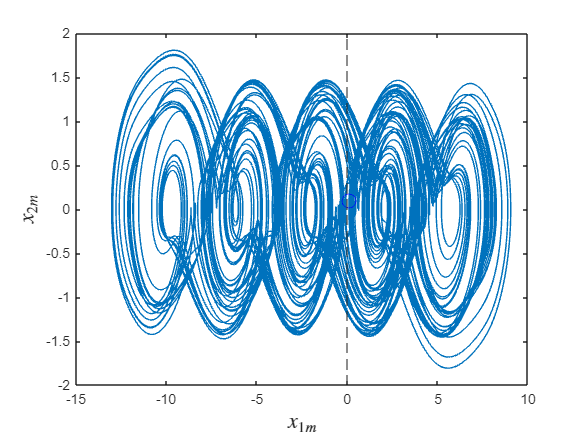

figure(1)
plot(x1m,x2m); hold on;
plot(x1m(1),x2m(1),"Color",[0 0 1],"Marker","o","MarkerSize",10)
xline(0,"LineStyle","--"); hold off;
xlabel('$x_{1m}$','interpreter','latex','FontSize',16)
ylabel('$x_{2m}$','interpreter','latex','FontSize',16)

## Sección 2: Sincronización

En este estudio se presenta un esquema maestro-esclavo basado en un observador para resolver el problema de sincronización de un sistemas caóticos de múltiple enrollamiento. Para brindar robustez al esquema de sincronización, un observador de estado extendido es considerado como sistema esclavo para estimar todos los estados del sistema maestro y la no linealidad que genera los múltiples enrollamientos. Es decir, el término no lineal se considera como una función desconocida. Así, en un esquema de encriptamiento, el usuario podrá ajustar los parámetros del término no lineal de manera arbitraria y el observador estimará la no linealidad sin necesidad de conocer dicha información.

El observador de estado extendido está definido de la siguiente manera:


$$\dot{x}_{1s} = 10\big(x_{2m} + l_{1}(x_{1m}-x_{1s})\big), \\
\dot{x}_{2s} = 10\big(x_{3m} + l_{2}(x_{1m}-x_{1s})\big), \\
\dot{x}_{3s} = 10\big(-ax_{2m} - cx_{3m} + x_{4} + l_{3}(x_{1m}-x_{1s})\big), \\
\dot{x}_{4s} = 10l_{4}(x_{1m}-x_{1s}).$$


Para fines de estudio, las ganancias $l_{i}\ (i=1,2,3,4.)$ del observador fueron sintonizadas por colocación de polos, con $l_{1} = \frac{2}{5}\omega_{0}-c, \ l_{2} = \frac{3}{50}\omega_{0}^{2} - c l_{1},\ l_{3} = \frac{2}{500}\omega_{0}^{3} - a - cl_{2},\ l_{4} = \frac{1}{10000}\omega_{0}^{4}$$ y

% Ganancias del observador
omega_0 = 40;
l1 = (2/5)*omega_0 - c;

Unrecognized function or variable 'c'.

l2 = (3/20)*omega_0^2 - c*l1;
l3 = (2/500)*omega_0^3 - a -c*l2;
l4 = (1/10000)*omega_0^4;
t0 = 0;             % Tiempo inicial
tf = 100;           % Tiempo final
dt = 1e-3;          % Paso de integracion
t = (t0:dt:tf)';    % Tiempo

N = length(t);      % Numero de pasos


Las condiciones iniciales para el observador son las siguientes $[x_{1m}(0), x_{2m}(0), x_{3m}(0)]^{T}  = 0.1 \in \mathbb{R}^{3}.$

%Condiciones iniciales
x1s = zeros(N,1);
x2s = zeros(N,1);
x3s = zeros(N,1);
x4s = zeros(N,1);

x1s(1) = 1.1;
x2s(1) = 2;
x3s(1) = 0.6;
x4s(1) = 1.2;

%Iteraciones
for k=1:N-1
    x1s(k+1) = x1s(k) + dt*10*(x2s(k) + l1*(x1m(k)-x1s(k)));
    x2s(k+1) = x2s(k) + dt*10*(x2s(k) + l2*(x1m(k)-x1s(k)));
    x3s(k+1) = x3s(k) + dt*10*(-a*x2s(k) - c*x3s(k) + x4s(k) + l4*(x1m(k)-x1s(k)));
    x4s(k+1) = x4s(k) + dt*10*l4*(x1m(k)-x1s(k));
end

A continuacion, el plan de fase $(x_{1m},x_{2m})$

plot(x1m,x2m); hold on
plot(x1s,x2s,"Color",[1 0 0],"LineStyle","--")
plot(x1m(1),x2m(1),"Color",[0 0 1],"Marker","o","MarkerSize",10)
plot(x1s(1),x2s(1),"Color",[0 0 0],"Marker","square","MarkerSize",10)
xline(0,"LineStyle","--"); hold off
L = legend('$x_{m}$','$x_{s}$', 'location', 'southeast');
set(L, 'interpreter', 'latex', 'fontsize',16)
xlabel('$x_{1m}$','interpreter','latex','FontSize',16)
ylabel('$x_{2m}$','interpreter','latex','FontSize',16)

## Recursos Adicionales

N/A

## Referencias 

- Abundiz-Pérez, F., Cruz-Hernández, C., Murillo-Escobar, M., López-Gutiérrez, R., y Arellano-Delgado, A. (2016). A fingerprint image encryption scheme based on hyperchaotic r¨ossler map. Mathematical Problems in Engineering, 2016.

- Bonny, T., Nassan, W. A., Vaidyanathan, S., y Sambas, A. (2023). Highlysecured chaos-based communication system using cascaded masking technique and adaptive synchronization. Multimedia Tools and Applications, pp.1–30.

- Carbajal-Gómez, V. y Sánchez-López, C. (2019). Determining accurate Lyapunov exponents of a multiscroll chaotic attractor based on SNFS. Nonlinear Dynamics, 98(3):2389–2402.

- Chen, Z., Wen, G., Zhou, H., y Chen, J. (2017). Generation of grid multi-scroll chaotic attractors via hyperbolic tangent function series. Optik, 130:594–600.

- Ding, P. y Feng, X. (2020). Generation of multi-scroll chaotic attractors from a jerk circuit with a special form of a sine function. Electronics, 9(5):842.

- Gámez-Guzmán, L., Cruz-Hernández, C., López-Gutiérrez, R., y García-Guerrero, E. (2009). Synchronization of chuas circuits with multi-scroll attractors: application to communication. Communications in Nonlinear Science and Numerical Simulation, 14(6):2765–2775.

- Kekha Javan, A. A., Zare, A., Alizadehsani, R., y Balochian, S. (2022). Robust multi-mode synchronization of chaotic fractional order systems in the presence of disturbance, time delay and uncertainty with application in secure communications. Big Data and Cognitive Computing, 6(2):51.

- Li, F. y Zeng, J. (2023). Multi-scroll attractor and multi-stable dynamics of a three-dimensional jerk system. Energies, 16(5):2494.

- Li, Q. y Yue, C. (2020). Predefined-time modified function projective synchronization for multiscroll chaotic systems via sliding mode control technology. Complexity, 2020:1–11.

- Liu, S., Wei, Y., Liu, J., Chen, S., y Zhang, G. (2020). Multi-scroll chaotic system model and its cryptographic application. International Journal of Bifurcation and Chaos, 30(13):2050186.

- Lorenz, E. N. (1963). Deterministic nonperiodic flow. Journal of the Atmospheric Sciences, 20:130–141.

- Murillo-Escobar, M. A., Cardoza-Avendaño, L., López-Gutiérrez, R. M., y Cruz-Hern´andez, C. (2017). A double chaotic layer encryption algorithm for clinical signals in telemedicine. Journal of medical systems, 41:1–17.

- Nijmeijer, H. y Mareels, I. M. (1997). An observer looks at synchronization. IEEE Transactions on Circuits and Systems I: Fundamental theory and applications, 44(10):882–890. 

- Pecora, L. M. y Carroll, T. L. (1990). Synchronization in chaotic systems. Physical review letters, 64(8):821. 

- Pérez-Cruz, J. H., Portilla-Flores, E. A., Niño-Suárez, P. A., y Rivera-Blas, R. (2017). Design of a nonlinear controller and its intelligent optimization for exponential synchronization of a new chaotic system. Optik, 130:201–212.

- Roldán-Caballero, Alfredo and Pérez-Cruz, J Humberto and Hernández-Márquez, Eduardo and García-Sánchez, José Rafael and Ponce-Silva, Mario and Rubio, Jose de Jesus and Villarreal-Cervantes, Miguel Gabriel and Martínez-Martínez, Jesús and García-Trinidad, Enrique and Mendoza-Chegue, Alejandro and others (2023). Synchronization of a new chaotic system using adaptive control: Design and experimental implementation. Complexity, 2023.

- Rossler, O. E. (1979). An equation for hyperchaos. Physics Letters A, 71:155–157.

- Signing, V. F., Kengne, J., y Pone, J. M. (2019). Antimonotonicity, chaos, quasiperiodicity and coexistence of hidden attractors in a new simple 4-d chaotic system with hyperbolic cosine nonlinearity. Chaos, Solitons & Fractals, 118:187–198.

- Sira-Ramirez, H. y Cruz-Hernández, C. (2001). Synchronization of chaotic systems: A generalized hamiltonian systems approach. International Journal of bifurcation and chaos, 11(05):1381–1395.

- Sprott, J. C. (1994). Some simple chaotic flows. Physical review E, 50(2):R647.

- Tlelo-Cuautle, E., Carbajal-Gomez, V., Obeso-Rodelo, P., Rangel-Magdaleno, J., y Nunez-Perez, J. C. (2015). Fpga realization of a chaotic communication system applied to image processing. Nonlinear Dynamics, 82:1879–1892.

- Wang, F. y Xiao, Y. (2020). A multiscroll chaotic attractors with arrangement of saddle-shapes and its field programmable gate array (fpga) implementation. Complexity, 2020.

- Yujun, N., Xingyuan, W., Mingjun, W., y Huaguang, Z. (2010). A new hyperchaotic system and its circuit implementation. Communications in Nonlinear Science and Numerical Simulation, 15(11):3518–3524.

- Zambrano-Serrano, E., Munoz-Pacheco, J. M., Serrano, F. E., Sánchez-Gaspariano, L. A., y Volos, C. (2021). Experimental verification of the multi-scroll chaotic attractors synchronization in pwl arbitrary-order systems using direct coupling and passivity-based control. Integration, 81:56–70.

- Zhang, X. y Wang, C. (2019). A novel multi-attractor period multi-scroll chaotic integrated circuit based on cmos wide adjustable cccii. IEEE Access, 7:16336–16350.